#### Load data

behav.whiskerTrackingData = ...
    load('Z:\Vincent\Ephys\vIRt47\vIRt47_0805\Analysis\vIRt47_0805_5955\vIRt47_0805_5955_wMeasurements.mat');
whiskerAngleRaw=behav.whiskerTrackingData.Angle_raw;
whiskerAngle=WhiskingFun.BandPassBehavData(fillmissing(whiskerAngleRaw,'spline'),1000,[3 30]); % bandpass filtered 4 to 30 Hz see WhiskingFun.BandPassBehavData
[whiskerAngle,outliersIdx]=rmoutliers(whiskerAngle);
whiskerVelocity=behav.whiskerTrackingData.Velocity(~outliersIdx);
whiskerPhase=behav.whiskerTrackingData.Phase(~outliersIdx);
whiskerAmplitude=behav.whiskerTrackingData.Amplitude(~outliersIdx);
%     whiskerFrequency=behav.whiskerTrackingData.Freq(~outliersIdx);
whiskerSetPoint=behav.whiskerTrackingData.SetPoint(~outliersIdx);

#### Compute whisking frequency 

whisksIdx = bwconncomp(diff(whiskerPhase)>0);
peakIdx = zeros(1,length(whiskerVelocity));
peakIdx(cellfun(@(whisk) whisk(1), whisksIdx.PixelIdxList))=1;
whiskerFrequency=movsum(peakIdx,behav.whiskerTrackingData.samplingRate);

#### Find whisking epochs

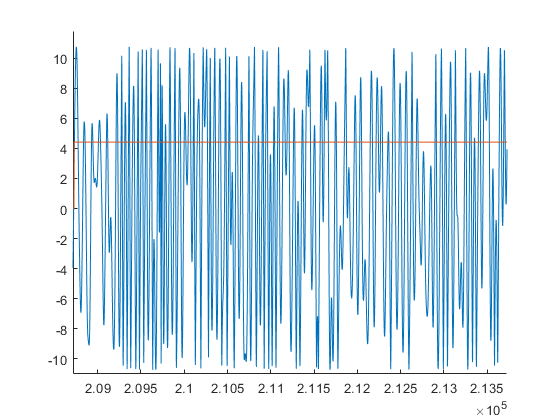

ampThd=12; %12; %18 %amplitude threshold
freqThld=1; %frequency threshold
minBoutDur=500; %500; % 1000 % minimum whisking bout duration: 1s
whiskingEpochs=WhiskingFun.FindWhiskingEpochs(...
    whiskerAmplitude(1,:),whiskerFrequency(1,:),...
    ampThd, freqThld, minBoutDur);
whiskingEpochs(isnan(whiskingEpochs))=false; %just in case
whiskingEpochsList=bwconncomp(whiskingEpochs);
[~,wBoutDurSort]=sort(cellfun(@length,whiskingEpochsList.PixelIdxList),'descend');
whiskingEpochsList.PixelIdxListSorted=whiskingEpochsList.PixelIdxList(wBoutDurSort);

figure; hold on;
plot(whiskerAngle);
plot(whiskingEpochs*nanstd(whiskerAngle)+nanmean(whiskerAngle))

xlim([208715 213728])
ylim([-11.0 11.8])

#### Segment

whiskingPeriods= whiskerAngle(whiskingEpochs); whiskingPeriods=whiskingPeriods-nanmean(whiskingPeriods);
restPeriods= whiskerAngle(~whiskingEpochs); restPeriods=restPeriods-nanmean(restPeriods);
fullTrace= whiskerAngle; restPeriods=restPeriods-nanmean(restPeriods);

% cellfun(@numel, whiskingEpochsList.PixelIdxList)
[whiskingExcerpts,restExcerpts,fullTraceExcerpts]=deal(nan(floor(min([numel(whiskingPeriods)/3500 numel(restPeriods)/3500])),3500));
for excerptNum=1:size(whiskingExcerpts,1)
    whiskingExcerpts(excerptNum,:)=whiskingPeriods((excerptNum-1)*3500+1:excerptNum*3500);
    restExcerpts(excerptNum,:)=restPeriods((excerptNum-1)*3500+1:excerptNum*3500);
    fullTraceExcerpts(excerptNum,:)=fullTrace((excerptNum-1)*3500+1:excerptNum*3500);
end


#### Power spectrum

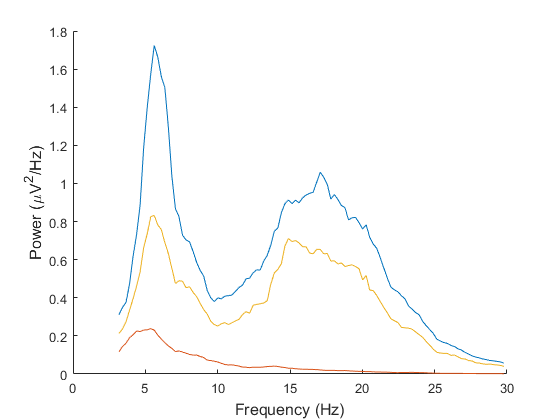

params.pad   = 0;                           % padding factor for the FFT (padding to the next highest power of 2)
params.Fs    = 1000;                        % sampling frequency
params.fpass = [3 30];                      % frequency band to be used in the calculation in the form [fmin fmax]
params.err   = [1 .05];                     % error calculation
                                                %	[1 p] - Theoretical error bars;
                                                %	[2 p] - Jackknife error bars
                                                %	[0 p] or 0 - no error bars
params.trialave = 1;                        % average over trials/channels
params.NW = 3.5; %3.5;                        % time-bandwidth product. E.g., 3.5s segment at 1.5 Hz makes p=NW=1.5*3.5=5.25 ~=5.5 (use K=10 tapers)
params.tapers = [params.NW (2*params.NW)-1];% the second value is the number of tapers to be used

[Sw,~]=mtspectrumc(whiskingExcerpts',params);
[Sr,~]=mtspectrumc(restExcerpts',params);
[Sf,freq]=mtspectrumc(fullTraceExcerpts',params);

figure; hold on
plot(freq,Sw);
plot(freq,Sr);
plot(freq,Sf);
xlabel('Frequency (Hz)','fontsize',12);
ylabel('Power (\muV^2/Hz)','fontsize',12);

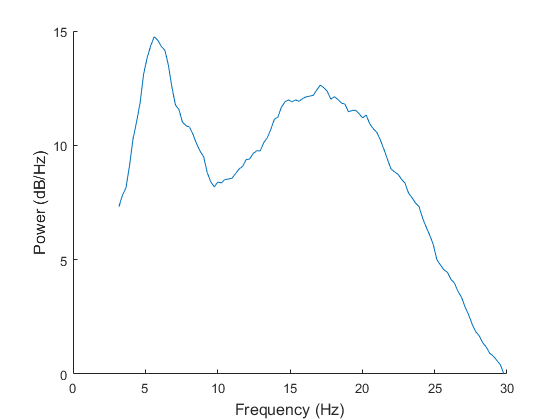


figure; hold on
plot(freq,10*log10(Sw/min(Sw)));
xlabel('Frequency (Hz)','fontsize',12);
ylabel('Power (dB/Hz)','fontsize',12);

#### Calculate standard deviation

% Pxx_std = stdPxx,[],2);
Pxx_sem = std(Pxx,[],2)/sqrt(length(Pxx));
Pxx_sd = std(Pxx,[],2);
Pxx_mean = mean(Pxx, 2);

upper = S + Pxx_sem;
lower = S - Pxx_sem;
%upper = Pxx_mean + Pxx_sd;
%lower = Pxx_mean - Pxx_sd;

y = cat(2, upper, lower);
y = y';
x = f_w'; % or f_b in the case of breathing data

%patch([1: length(curve1), length(curve2): -1: 1], [curve1', flipud(curve2)'], 'r', 'facealpha', 0.3);
%X indicate a closed polygon, so starting from 1 along the upper/lower curve to the rightmost point, 50 here,
% and then come back along the lower/upper curve from 50 to 1. Y is the corresponding y value of X.

pink = [205/255, 86/255, 82/255];
gold = [205/255, 195/255, 50/255];
aqua = [72/255, 129/255, 181/255];


px=[x,fliplr(x)]; % make closed patch
py=[y(1,:), fliplr(y(2,:))];
patch(px,py,1,'FaceColor',aqua,'facealpha', 0.3, 'EdgeColor','none');

hold on;
% plot(x, Pxx_mean, 'Color',aqua, 'LineWidth', 1);
% xlim([0 25])
plot(freq,S, 'Color',aqua, 'LineWidth', 1);
fUpLimIdx=find(freq>=25,1); xlim([0 fUpLimIdx]);
lowTickLim=find(freq>=1,1);
set(gca,'xtick',lowTickLim:10:max(get(gca,'xtick'))+lowTickLim,'xticklabel',...
    round(freq(lowTickLim:10:max(get(gca,'xtick'))+lowTickLim),1))
xlabel('Frequency (Hz)')
ylabel('Power (\muV^2/Hz)')